**This code loads monthly rate of change of inflation. **Data is extracted from Eurostat and shows national data for 11 european countries between 2019 and 2023.

load inflation % loads table of data
inflation([7,10,1],:)=[]; % removing some country data to create more comprehensive visualizations
time=linspace(2019,2023,48) % vector of equally spaced elements for timeline

time = 1.0e+03 *

    2.0190    2.0191    2.0192    2.0193    2.0193    2.0194    2.0195    2.0196    2.0197    2.0198    2.0199    2.0199    2.0200    2.0201    2.0202    2.0203    2.0204    2.0204    2.0205    2.0206    2.0207    2.0208    2.0209    2.0210    2.0210    2.0211    2.0212    2.0213    2.0214    2.0215    2.0216    2.0216    2.0217    2.0218    2.0219    2.0220    2.0221    2.0221    2.0222    2.0223    2.0224    2.0225    2.0226    2.0227    2.0227    2.0228    2.0229    2.0230


data1=inflation{:,2:end} % extracting data from table

data1 =     1.1000    1.0000    0.9000    0.9000    1.2000    1.5000    1.6000    1.7000    1.3000    0.8000    0.5000    0.8000         0   -0.1000   -0.4000   -0.5000   -0.7000   -0.7000    1.6000    1.6000    2.0000    2.1000    2.4000    2.1000    3.1000    3.4000    4.1000    4.6000    6.0000    5.7000    5.1000    5.5000    7.6000    7.8000    8.7000    8.2000    8.5000    8.8000   10.9000   11.6000   11.3000    9.6000    9.2000    9.3000    7.8000    7.6000    6.3000    6.8000
    0.6000    0.4000    0.2000    0.2000    0.5000    0.8000    1.1000    0.9000    0.1000   -0.7000   -0.9000   -0.3000   -0.7000   -0.6000   -0.6000   -0.9000   -0.8000   -0.6000    0.4000   -0.1000    1.2000    2.0000    2.4000    2.5000    2.9000    3.3000    4.0000    5.4000    5.5000    6.6000    6.2000    7.6000    9.8000    8.3000    8.5000   10.0000   10.7000   10.5000    9.0000    7.3000    6.7000    5.5000    5.9000    6.0000    3.1000    3.8000    2.9000    1.6000
    1.3000    1.3000    1.1000

inflation.Properties.VariableNames(1)={'Countries'}

inflation = 8×49 table
        Countries         VarName2    VarName3    VarName4    VarName5    VarName6    VarName7    VarName8    VarName9    VarName10    VarName11    VarName12    VarName13    VarName14    VarName15    VarName16    VarName17    VarName18    VarName19    VarName20    VarName21    VarName22    VarName23    VarName24    VarName25    VarName26    VarName27    VarName28    VarName29    VarName30    VarName31    VarName32    VarN

countries=inflation.Countries % string of country names

countries = 8×1 cell array
    {'Germany '      }
    {'Spain'         }
    {'France'        }
    {'Italy'         }
    {'Portugal'      }
    {'Sweden'        }
    {'Norway'        }
    {'United Kingdom'}


MissingValues=isnan(data1); % logical array for accounting missing data
HowManyMissing=nnz(MissingValues) 

HowManyMissing = 33

disp('There are 33 missing data points in Data Array')

There are 33 missing data points in Data Array


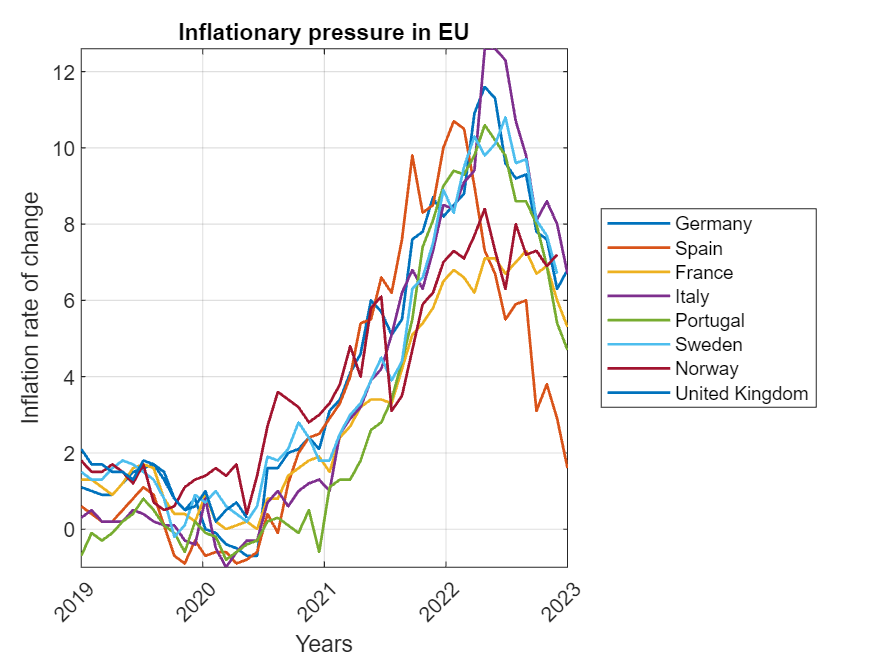

plot(time,data1,'linewidth',1.3)
grid on
axis tight
xlabel('Years')
xtickangle(45)
ylabel('Inflation rate of change')
title('Inflationary pressure in EU')
legend(countries,'Location','eastoutside')

**This code smooths the data over time in order to remove noise. **Smoothing is done across rows so that each data point becomes the mean of itself and 2 data points behind it, and 2 data points after it.

data1Sm=smoothdata(data1','movmean',[2,2]) 

data1Sm =     1.0000    0.4000    1.2333    0.3333   -0.3667    1.3667    1.6000    1.8333
    0.9750    0.3500    1.1500    0.3000   -0.3000    1.4250    1.6250    1.7500
    1.0200    0.3800    1.1600    0.2800   -0.2000    1.5000    1.6000    1.7000
    1.1000    0.4200    1.2200    0.3200    0.0200    1.5400    1.4800    1.5400
    1.2200    0.5600    1.3000    0.3000    0.2000    1.5800    1.5200    1.5600
    1.3800    0.7000    1.4000    0.3000    0.3600    1.5800    1.3600    1.5600
    1.4600    0.6800    1.3800    0.2800    0.4000    1.4200    1.1200    1.5600
    1.3800    0.4400    1.2200    0.2600    0.3400    1.0200    0.9400    1.4200
    1.1800    0.1000    0.9800    0.1000    0.1400    0.7000    0.9200    1.2600
    1.0200   -0.1800    0.6800   -0.0600    0.0200    0.5800    0.8400    1.0200


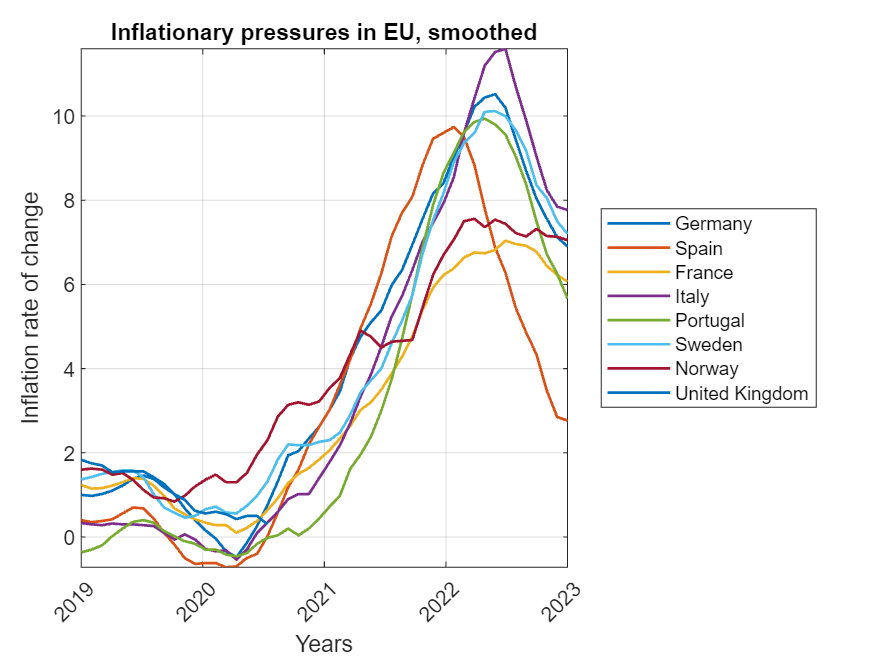

% smoothing data with a moving mean window (for each nation) of 2 points
% back and forwards
plot(time,data1Sm,'linewidth',1.3)
grid on
axis tight
xlabel('Years')
xtickangle(45)
ylabel('Inflation rate of change')
title('Inflationary pressures in EU, smoothed')
legend(countries,'Location','eastoutside')

disp('DATA SMOOTHING IS NECESSARY TO UNCOVER TRENDS IN DATA')

DATA SMOOTHING IS NECESSARY TO UNCOVER TRENDS IN DATA


**Before dealing with NaNs, a POLYNOMIAL REGRESSION MODEL (model linear in coefficients) is estimated for the mean inflation change for each time period. This is the model that can best summarize the depicted data.**

For the UK, estimating NaNs through interpolation cannot work  because sequential elements of the row are NaNs: regression will be used to estimate these values:

data1mean=mean(data1,'omitnan') % mean across columns= time periods

data1mean =     1.0000    0.9500    0.8250    0.8625    1.0125    1.1250    1.3250    1.0750    0.6500    0.2125    0.1000    0.4125    0.5000    0.2000   -0.0375    0.0375   -0.1375    0.0143    1.1857    1.2857    1.5429    1.8000    1.9286    1.7143    2.1000    2.7429    3.2571    3.6429    4.4429    4.7571    4.3000    5.1143    6.5429    6.8143    7.4429    8.3000    8.4857    8.7000    9.0429    9.6286    9.3286    8.7143    8.4286    8.2714    7.0143    6.9143    6.0714    5.0200


% INFLATION DATA BECOMES ONE VECTOR OF MEAN EU VALUES FOR EACH TIME PERIOD
scatter(time,data1mean,25,'k','filled')
grid on
axis tight
xlabel('Years')
xtickangle(45)
ylabel('Inflation rate of change in %')
title('Mean inflation in EU, scatter')
disp('A model of best fit is a polynomial model, linear in its coefficients')

A model of best fit is a polynomial model, linear in its coefficients


[polinomio,~,scales]=polyfit(time,data1mean,5) % in order to plot and scale the polynomial fit

polinomio =    -0.0801   -1.2274   -1.3315    3.6854    5.5175    2.1471


scales = 1.0e+03 *

    2.0210
    0.0012


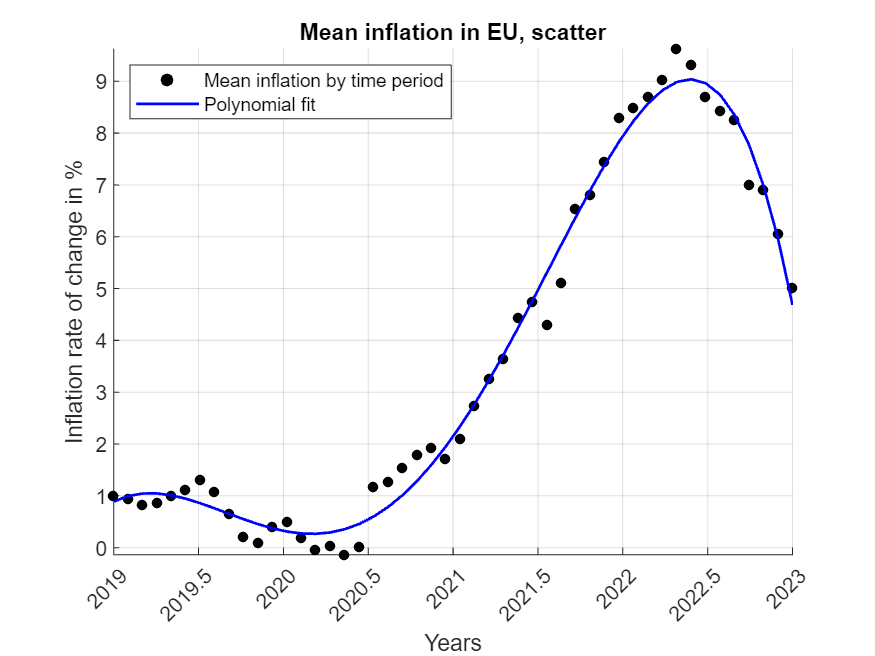

fittedMean=polyval(polinomio,time,[],scales);
hold on
plot(time,fittedMean,'b','linewidth',1.3)
hold off
legend('Mean inflation by time period','Polynomial fit','Location','northwest')

[RegressModel,GoodnessFit]=fit(time',data1mean','poly5')

RegressModel =      Linear model Poly5:
     RegressModel(x) = p1*x^5 + p2*x^4 + p3*x^3 + p4*x^2 + p5*x + p6
     Coefficients (with 95% confidence bounds):
       p1 =   -0.001397  (-0.004799, 0.002006)
       p2 =       13.49  (-20.86, 47.84)
       p3 =  -5.202e+04  (-1.907e+05, 8.671e+04)
       p4 =       1e+08  (-1.8e+08, 3.801e+08)
       p5 =  -9.597e+10  (-3.787e+11, 1.868e+11)
       p6 =   3.672e+13  (-7.747e+13, 1.509e+14)

GoodnessFit = struct with fields:
           sse: 6.1113
       rsquare: 0.9880
           dfe: 42
    adjrsquare: 0.9866
          rmse: 0.3815


RSQUARED=GoodnessFit.rsquare

RSQUARED = 0.9880

residuals=fittedMean-data1mean;
SQresiduals=residuals.^2;
SSR=sum(SQresiduals) % sum of squared residuals

SSR = 6.0277

n=length(data1mean);
df=n-(length(polinomio)+1) % degrees of freedom 

df = 41

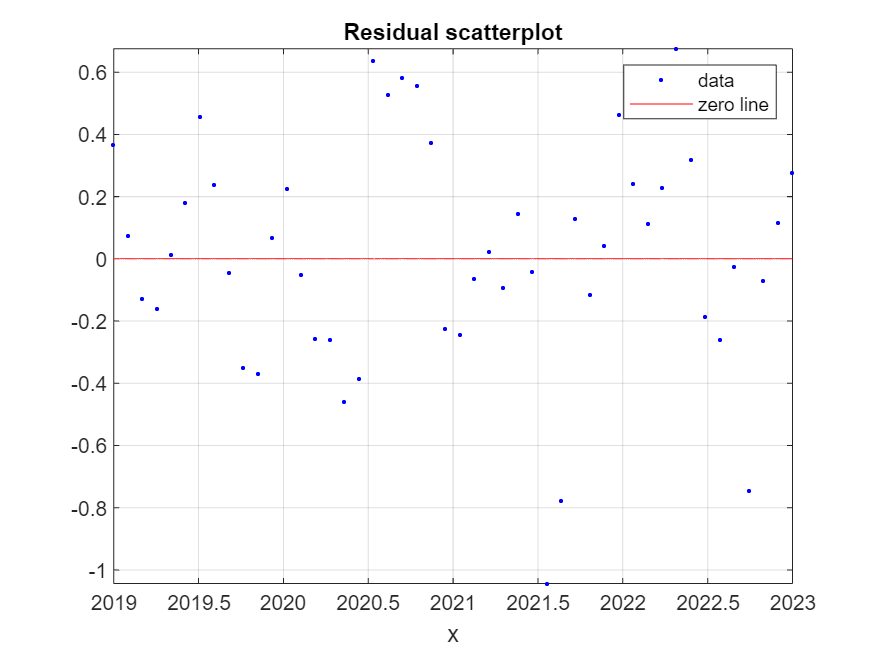

VarRes=SSR/df; % estimated residual variance
plot(RegressModel,time',data1mean','residuals')
grid on
axis tight
title('Residual scatterplot')

disp('The residuals do not display a clear pattern and seem to be normally distributed')

The residuals do not display a clear pattern and seem to be normally distributed


**Missing data points are estimated through interpolation in some case and  polynomial regression in another case:**

The case of the UK is complicated: data estimated using polynomial fitting might be erroneous due to issues related to feature scaling or overfitting.

countries(1)={'Germany'};
countries(end)={'UK'}

countries = 8×1 cell array
    {'Germany' }
    {'Spain'   }
    {'France'  }
    {'Italy'   }
    {'Portugal'}
    {'Sweden'  }
    {'Norway'  }
    {'UK'      }


nation="Sweden" % drop down menu for each nation

nation = "Sweden"

log1=strcmp(nation,countries); % logical with true for nation index
nationIndex=find(log1) % row number for data of chosen country

nationIndex = 6

nationData=data1(nationIndex,:)

nationData =     1.5000    1.3000    1.3000    1.6000    1.8000    1.7000    1.5000    1.3000    0.8000   -0.2000    0.1000    0.9000    0.7000    1.0000    0.6000    0.4000    0.2000    0.6000    1.9000    1.8000    2.1000    2.8000    2.4000    1.8000    1.8000    2.5000    3.0000    3.3000    3.9000    4.5000    3.9000    4.4000    6.3000    6.6000    7.5000    8.9000    8.3000    9.5000   10.3000    9.8000   10.1000   10.8000    9.6000    9.7000    8.1000    7.7000    6.7000       NaN


missingValues=ismissing(nationData); % logical for NaNs
missing=nnz(missingValues) % number of missing values to interpolate

missing = 1

indMissing = 48

time_Predict = 2023

inf_Estim = 5.3571

fitted =     0.8900    0.9961    1.0451    1.0467    1.0100    0.9440    0.8571    0.7572    0.6519    0.5483    0.4529    0.3719    0.3107    0.2744    0.2673    0.2935    0.3561    0.4578    0.6005    0.7857    1.0141    1.2857    1.5997    1.9548    2.3488    2.7787    3.2410    3.7311    4.2437    4.7727    5.3112    5.8512    6.3841    6.9003    7.3892    7.8393    8.2382    8.5726    8.8279    8.9889    9.0391    8.9610    8.7361    8.3448    7.7664    6.9790    5.9597    4.6845


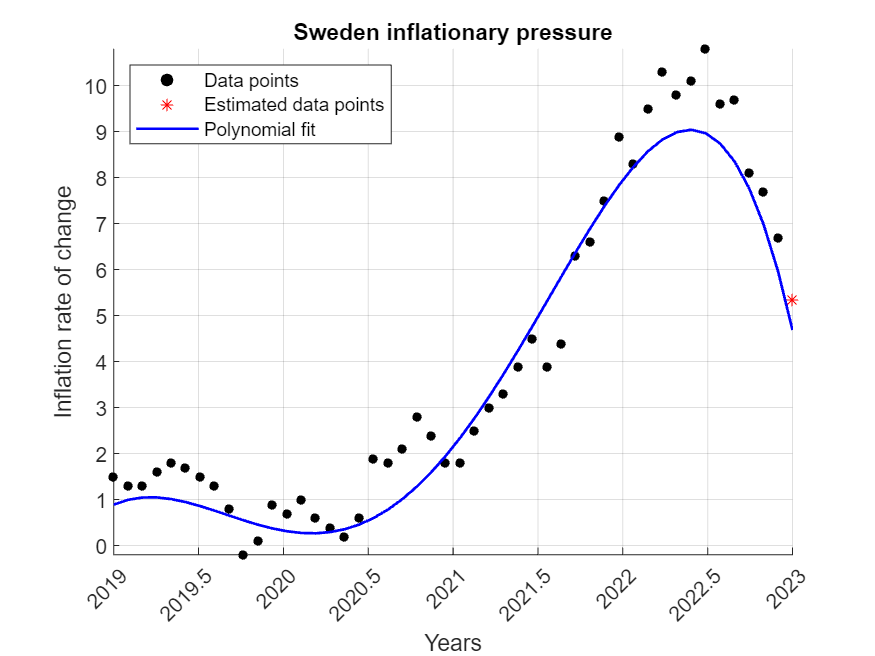

% THE IF STATEMENT: DECIDES THE NEED TO ESTIMATE MISSING DATA
if missing==0
    msgbox('No need for interpolation = no missing values','Message')
    scatter(time,nationData,20,'k','filled')
    grid on
    axis tight
    xlabel('Years')
    xtickangle(45)
    ylabel('Inflation rate of change')
    title(nation+' inflationary pressure')
    polynom=polyfit(time,nationData,5) % best fit for the data
    fittedData=polyval(polynom,time)
    hold on
    plot(time,fittedData,'b','linewidth',1.3)
    hold off
    legend('Data points','Polynomial fit','Location','southeast')
elseif missing>0 && nation==countries(end)
    scatter(time,nationData,20,'k','filled')
    grid on
    axis tight
    xlabel('Years')
    xtickangle(45)
    ylabel('Inflation rate of change')
    title(nation+' inflationary pressure')
    mtime=time(missingValues)
    norm_time=normalize(mtime,'range',[0,1]) % x to be subsituted for prediction
    b5=polinomio(1)
    b4=polinomio(2)
    b3=polinomio(3)
    b2=polinomio(4)
    b1=polinomio(5)
    b0=polinomio(end)
    missing_data=b0-b1.*norm_time+b2.*norm_time.^2-b3.*norm_time.^3+b4.*norm_time.^4-b5.*norm_time.^5
    hold on
    plot(mtime,missing_data,'r*')
    hold off
elseif missing>0 
    indMissing=find(missingValues) % index of missing data points
    time_Predict=time(indMissing) % time period within missing data
    inf_Estim=interp1(time,nationData,time_Predict,'pchip') 
    scatter(time,nationData,20,'k','filled')
    grid on
    axis tight
    xlabel('Years')
    xtickangle(45)
    ylabel('Inflation rate of change')
    title(nation+' inflationary pressure')
    hold on
    plot(time_Predict,inf_Estim,'r*')
    hold off
    % FITTING A POLYNOMIAL AFTER NANS ARE ESTIMATED 
    [polinom,~,scales]=polyfit(time,data1mean,5); % in order to plot and scale the polynomial fit
    fitted=polyval(polinom,time,[],scales)
    hold on
    plot(time,fitted,'b','linewidth',1.3)
    hold off
    legend('Data points','Estimated data points','Polynomial fit','Location','northwest')
else 
end 

**Forecasting future inflationary pressure: **the goal is to forecast mean EU inflation for 2024 and 2025 using various regression models:

Different regression models show very different results according to the nature of the regression:

disp('Inflation forecast for years 2024 and 2025')

Inflation forecast for years 2024 and 2025


years=[2024,2025]'; % column array needed
time_forecast1=polyval(polinomio,years);
infl_POLYNOMIAL2024=time_forecast1(1)

infl_POLYNOMIAL2024 = -2.7400e+15

infl_POLYNOMIAL2025=time_forecast1(end)

infl_POLYNOMIAL2025 = -2.7468e+15

disp('Given the nature of polynomial fititng, these forecasts may be erronous in their estimation')

Given the nature of polynomial fititng, these forecasts may be erronous in their estimation


% fitting a line to mean inflationary data 
linearFit=fitlm(time,data1mean);
time_forecast2=predict(linearFit,years);
infl_LINEAR2024=time_forecast2(1)

infl_LINEAR2024 = 10.8815

infl_LINEAR2025=time_forecast2(end)

infl_LINEAR2025 = 13.2957

disp('The linear model forecasts augmenting inflation rates for both years as the slope is positive')

The linear model forecasts augmenting inflation rates for both years as the slope is positive


% trying to fit a sine model to forecast inflation
[sinModel,sinR]=fit(time',data1mean','sin1');
years_sine=linspace(2024,2025,48);
a1=sinModel.a1;
b1=sinModel.b1;
c1=sinModel.c1;
sine_rsquared=sinR.rsquare

sine_rsquared = 0.7486

infl_SIN2024=a1*sin(b1*years(1)+c1)

infl_SIN2024 = 9.8568

infl_SIN2025=a1*sin(b1*years(end)+c1)

infl_SIN2025 = 11.9189

disp('The sine regression model also forecasts augmenting inflation')

The sine regression model also forecasts augmenting inflation


**The final task is to regress inflation against GDP growth and unemployment in the chosen EU economies: BUILD A MULTIPLE LINEAR REGRESSION MODEL:**

GDP growth in % (expanded quaterly data, Eurostat) is the first independent variable in the regression model.

Monthly unemployment data (taken from Eurostat) is the second independent variable for the regression.

disp('MULTIPLE LINEAR REGRESSION OF INFLATION AGAINST GDP AND UNEMPL:')

MULTIPLE LINEAR REGRESSION OF INFLATION AGAINST GDP AND UNEMPL:


load gdp_growth
inflation

inflation = 8×49 table
        Countries         VarName2    VarName3    VarName4    VarName5    VarName6    VarName7    VarName8    VarName9    VarName10    VarName11    VarName12    VarName13    VarName14    VarName15    VarName16    VarName17    VarName18    VarName19    VarName20    VarName21    VarName22    VarName23    VarName24    VarName25    VarName26    VarName27    VarName28    VarName29    VarName30    VarName31    VarName32    VarN

gdp_growth.Properties.VariableNames(1)={'Countries'} % table of quaterly gdp growth rate in % from 2019 to 2023

gdp_growth = 8×17 table
        Countries          Q3      Q4      Q1      Q2       Q5      Q6      Q7     Q8     Q9     Q10    Q11     Q12     Q13    Q14     Q15     Q16 
    __________________    ____    ____    ____    _____    ____    ____    ____    ___    ___    ___    ____    ____    ___    ____    ____    ____

    {'Germany'       }       0     0.3    -1.8     -9.2     8.9     0.8    -1.3    2.2    0.7      0 

gdpdata=gdp_growth{:,2:end}; % we need to make the number of time period of gdp data
disp('Expanding gdp_growth data to match the size of inflation data')

Expanding gdp_growth data to match the size of inflation data


numRepeat=3 % number of times to repeat each column in gdpdata

numRepeat = 3

% Repeat each column and concatenate
gdp_exp=[];
for col=1:size(gdpdata,2)
    gdp_exp=[gdp_exp,repmat(gdpdata(:,col),1,numRepeat)];
end
gdp_exp(:,1)=[] % the result is 'gdp_exp' matching 'data1'

gdp_exp =          0         0    0.3000    0.3000    0.3000   -1.8000   -1.8000   -1.8000   -9.2000   -9.2000   -9.2000    8.9000    8.9000    8.9000    0.8000    0.8000    0.8000   -1.3000   -1.3000   -1.3000    2.2000    2.2000    2.2000    0.7000    0.7000    0.7000         0         0         0    1.0000    1.0000    1.0000   -0.1000   -0.1000   -0.1000    0.4000    0.4000    0.4000   -0.4000   -0.4000   -0.4000   -0.1000   -0.1000   -0.1000         0         0         0
    0.3000    0.3000    0.2000    0.2000    0.2000   -5.5000   -5.5000   -5.5000  -17.8000  -17.8000  -17.8000   16.6000   16.6000   16.6000   -0.1000   -0.1000   -0.1000   -0.2000   -0.2000   -0.2000    1.4000    1.4000    1.4000    3.1000    3.1000    3.1000    2.3000    2.3000    2.3000   -0.6000   -0.6000   -0.6000    2.8000    2.8000    2.8000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.5000    0.5000    0.5000    0.4000    0.4000    0.4000
    0.1000    0.1000   -0.4000   -0.4000   -0.40

data1(:,1)=[];
infl_data=data1 % for matching size of data matrices

infl_data =     1.0000    0.9000    0.9000    1.2000    1.5000    1.6000    1.7000    1.3000    0.8000    0.5000    0.8000         0   -0.1000   -0.4000   -0.5000   -0.7000   -0.7000    1.6000    1.6000    2.0000    2.1000    2.4000    2.1000    3.1000    3.4000    4.1000    4.6000    6.0000    5.7000    5.1000    5.5000    7.6000    7.8000    8.7000    8.2000    8.5000    8.8000   10.9000   11.6000   11.3000    9.6000    9.2000    9.3000    7.8000    7.6000    6.3000    6.8000
    0.4000    0.2000    0.2000    0.5000    0.8000    1.1000    0.9000    0.1000   -0.7000   -0.9000   -0.3000   -0.7000   -0.6000   -0.6000   -0.9000   -0.8000   -0.6000    0.4000   -0.1000    1.2000    2.0000    2.4000    2.5000    2.9000    3.3000    4.0000    5.4000    5.5000    6.6000    6.2000    7.6000    9.8000    8.3000    8.5000   10.0000   10.7000   10.5000    9.0000    7.3000    6.7000    5.5000    5.9000    6.0000    3.1000    3.8000    2.9000    1.6000
    1.3000    1.1000    0.9000    1.2000    1.

load unemp.mat
unemp.Properties.VariableNames(1)={'Countries'}

unemp = 8×48 table
        Countries         VarName2    VarName3    VarName4    VarName5    VarName6    VarName7    VarName8    VarName9    VarName10    VarName11    VarName12    VarName13    VarName14    VarName15    VarName16    VarName17    VarName18    VarName19    VarName20    VarName21    VarName22    VarName23    VarName24    VarName25    VarName26    VarName27    VarName28    VarName29    VarName30    VarName31    VarName32    VarName3

unem=unemp{:,2:end}

unem =     2.9000    2.9000    2.9000    2.9000    3.0000    3.1000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    3.9000    3.9000    3.9000    3.9000    3.9000    3.9000    3.9000    3.8000    3.7000    3.6000    3.5000    3.4000    3.4000    3.3000    3.3000    3.2000    3.2000    3.1000    3.0000    3.0000    3.0000    3.0000    3.0000    3.1000    3.1000    3.1000    3.1000    3.0000    3.0000    3.0000    3.0000    3.0000
   14.2000   14.2000   14.2000   14.0000   14.0000   13.9000   13.8000   13.8000   13.6000   14.5000   15.3000   15.5000   16.0000   16.3000   16.5000   16.4000   16.3000   16.2000   16.2000   15.7000   15.5000   15.3000   15.5000   15.5000   15.5000   15.2000   14.7000   14.2000   13.7000   13.4000   13.2000   13.2000   13.2000   13.2000   12.9000   12.7000   12.7000   12.7000   12.8000   12.9000   12.9000   13.0000   13.0000   13.0000   12.8000   12.5000   12.1000
    8.5000    8.4000    8.3000    8.2000    8.2000 

**Building the multiple model throught the 'fitlm' function:**

The regressors and the dependent variable are all given in percentages, so it is possible to interpret the coefficients as percentage changes.

disp('Finding mean EU data to analyse each variable as one vector')

Finding mean EU data to analyse each variable as one vector


unem=mean(unem,1,'omitnan');
inf=mean(infl_data,1,'omitnan');
gdp=mean(gdp_exp,1,'omitnan');
x=[gdp',unem'] % matrix of independent variables and ones column for intercept

x =     0.2500    7.0000
    0.2500    7.0875
    0.1750    7.1000
    0.1750    6.9625
    0.1750    7.0500
   -3.4375    7.1250
   -3.4375    7.0375
   -3.4375    7.1500
  -12.4125    7.0125
  -12.4125    6.7375


inf=inf';
multModel=fitlm(x,inf) 

multModel = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     28.257       4.9304     5.7311    8.3723e-07
    x1             0.17435     0.090279     1.9312      0.059917
    x2             -3.3229      0.66468    -4.9992    9.6663e-06


Number of observations: 47, Error degrees of freedom: 44
Root Mean Squared Error: 2.7
R-squared: 0.363,  Adjusted R-Squared: 0.334
F-statistic vs. constant model: 12.6, p-value = 4.86e-05

disp('Possible multicollinearity issue!')

Possible multicollinearity issue!


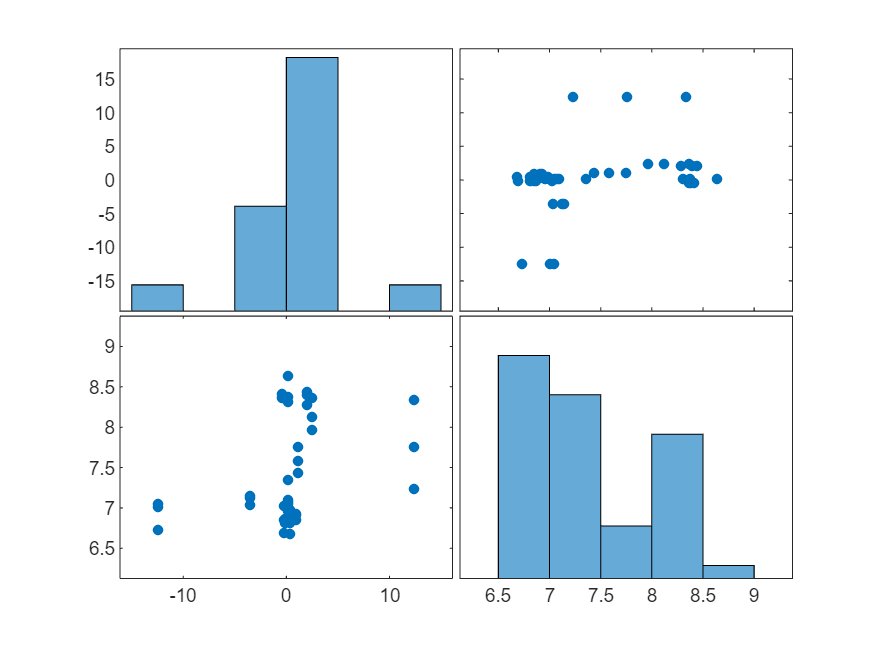

for_correlation=[gdp',unem'];
plotmatrix(x) % making sure there is no high collinearity due to correlation of regressors 

corr_GDP_unem=corrcoef(for_correlation)

corr_GDP_unem =     1.0000    0.3223
    0.3223    1.0000


disp('According to the correlation matrix, there is no high correlation between GDP and unemployment')

According to the correlation matrix, there is no high correlation between GDP and unemployment


disp('The second coefficient (unemployment regressor) is statistically significant.')

The second coefficient (unemployment regressor) is statistically significant.


disp('For every 1% increase in unemployment,inflation falls by 3.3229%.')

For every 1% increase in unemployment,inflation falls by 3.3229%.


disp('The first coefficient is marginally significant (for gdp regressor):')

The first coefficient is marginally significant (for gdp regressor):


disp('For every 1% extra growth of gdp, inflation increases by 0.17%.')

For every 1% extra growth of gdp, inflation increases by 0.17%.


disp('R-squared shows a low value of 36.3% = there are more regressors that may explain inflation ratees.')

R-squared shows a low value of 36.3% = there are more regressors that may explain inflation ratees.


% making predictions with the Multiple Model:
gdp_forecast=0.8 % mean EU GDP growth of 0.8%

gdp_forecast = 0.8000

unem_forecast=5.5 % 5.5% mean EU unemployment

unem_forecast = 5.5000

forecast_inf=predict(multModel,[gdp_forecast,unem_forecast]) % mean forecasted inflation

forecast_inf = 10.1203